Copyright © 2021  Shababuddin Khan  || sk@pcampus.edu.np

*Department of Electrical Engineering, *[Pulchowk Campus](https://pcampus.edu.np/)*, Tribhuwan University, Nepal*

A Series of  Module has been designed and developed by author mentioned above with full copyright for a course of **Control System** to demonstrante the concept of control system and its implementation in real life to second year Aerospace engineering students at Tribhuwan University.

# ***MODULE 5: Stability of Control System***

Stability is a standard requirement for control systems to avoid loss of control and damage to equipment. For linear feedback systems, stability can be assessed by looking at the poles of the closed-loop transfer function. 

The system whose transient period diesout as time tends to infinity, is reagarded as stable system. In this module, we will discuss the effect of location of closed loop roots of linear time invarient system on stability and types of system based on stability.

# 5.1 Effect of Variation of Pole's Location on Stability


$$G\left(s\right)=\frac{K}{\left(s+a+\mathrm{jb}\right)\left(s+a-\mathrm{jb}\right)}$$


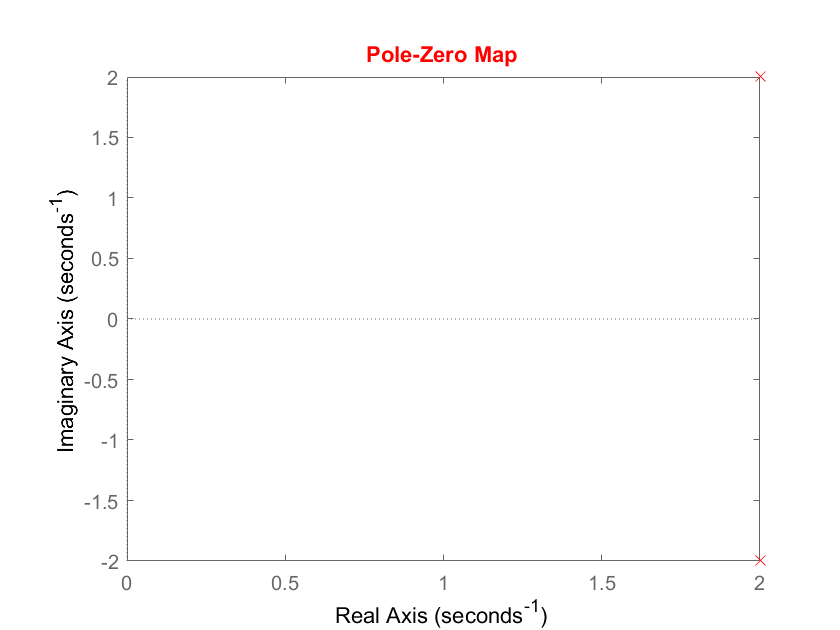

%Defining the System Parameter

%Real Part of Roots
a=-2;
%Imaginary Part of Roots
b=2;
%System Gain
K=(a^2+b^2);
% Defining the System
s=tf('s');
G=K/((s+(a+1j*b))*(s+(a-1j*b)));

%Plot Root and Poles
h=pzplot(G,'r');
p = getoptions(h);
p.Title.Color = [1,0,0];
setoptions(h,p);

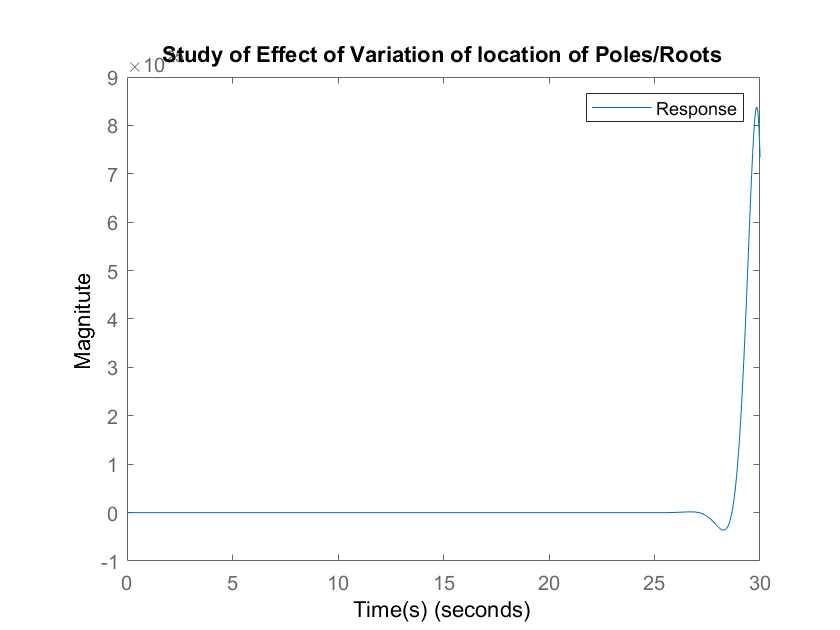

%grid

%Plot the System for unit step 
figure
step(G);
xlabel('Time(s)');
ylabel('Magnitute');
title('Study of Effect of Variation of location of Poles/Roots');
legend Response;


% % for Critically stable system
% h = stepplot(G); % Use this command to return plot handle to programmatically customize the plot. 
% p = getoptions(h);
% p.XLim = {[330.49, 397.472]};
% p.YLim = {[-0.5, 2.5]};
% setoptions(h,p);

# 5.2 Check Whether System is Stable or Not

%Use of isstable() command to check stability
x=isstable(G);
x

x = logical
   0


if x==1
   fprintf('System is Stable');
else
    fprintf('System is Not Stable');
end

System is Not Stable

# 5.3 Seperating Transient Resposne from total Response


$$G\left(s\right)=\frac{24}{s^2 +5s+24}$$


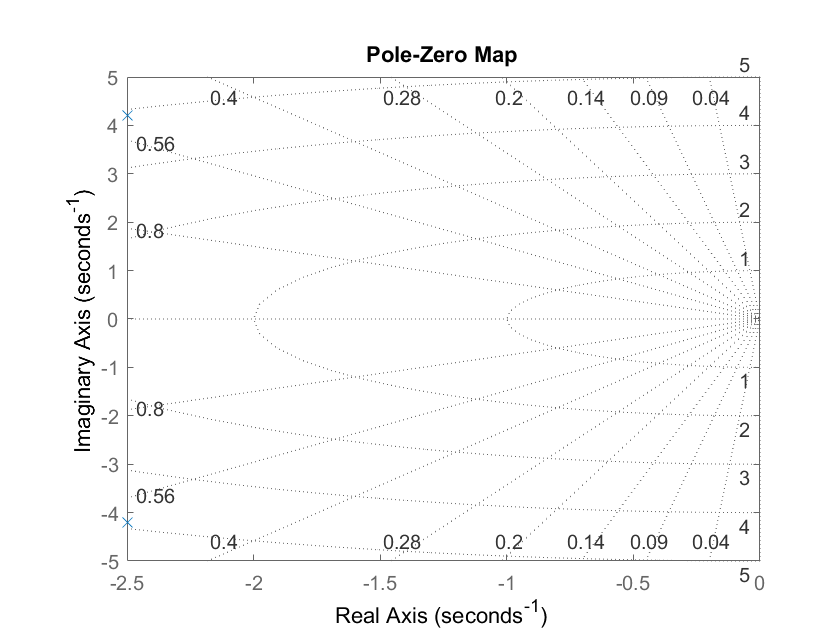

%To plot P_Z map
s=tf('s');
G=24/(s^2+5*s+24);
pzplot(G)
grid


% Defining the System
syms s;
G1=24/(s^2+5*s+24);    % Refer Example 2 of Lecture 3.4

% For Step Signal 
A=1;
R=A/s;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

$$c1 = 1-{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{71}\,t}{2}\right)+\frac{5\,\sqrt{71}\,\sin\left(\frac{\sqrt{71}\,t}{2}\right)}{71}\right)$$


%Steady Gain at s=0
SG=limit(G1,s,0)

$$SG = 1$$


%Transient Response Extraction from total response
% Transient Response=total-steady (i.e gain when s=0)
ct=c1-SG

$$ct = -{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{71}\,t}{2}\right)+\frac{5\,\sqrt{71}\,\sin\left(\frac{\sqrt{71}\,t}{2}\right)}{71}\right)$$

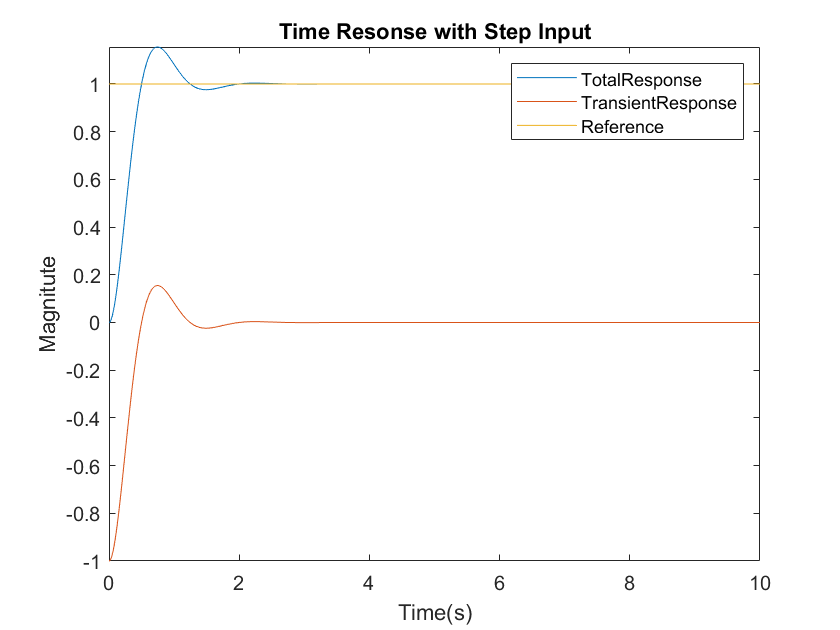


%Time Response of System
figure
fplot(c1,[0,10]);
hold on
fplot(ct,[0,10]);
fplot(r,[0,10]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Step Input');
legend TotalResponse TransientResponse Reference;

# 5.4 Stability Analysis Using R-H Criterion

The Routh-Hurwitz stability criterion is a necessary (and frequently sufficient) method to establish the stability of a single-input, single-output(SISO), linear time invariant (LTI) control system.

More generally, given a polynomial, some calculations using only the coefficients of that polynomial can lead us to the conclusion that it  is not stable.

**Note:** This program originally been written by Farzad Sagharchi ,Iran in   2007/11/12 and is modified and correctedd by Shahabuddin Khan on 28/06/2021.

## 5.4.1 Finding R-H Table

% Taking coefficients vector and organizing the first two rows
Coeff_CE_Vector = input('input vector of your system coefficients: \n i.e. [an an-1 an-2 ... a0] = ');
Row_RH_Table = length(Coeff_CE_Vector);
Col_RH_Table = round(Row_RH_Table/2);
%  Initialize Routh-Hurwitz table with empty zero array
RH_Table = zeros(Row_RH_Table,Col_RH_Table);

%  Compute first row of the table
RH_Table(1,:) = Coeff_CE_Vector(1,1:2:Row_RH_Table);

%  Check if length of coefficients vector is even or odd
if (rem(Row_RH_Table,2) ~= 0)
    % if odd, second row of table will be
    RH_Table(2,1:Col_RH_Table - 1) = Coeff_CE_Vector(1,2:2:Row_RH_Table);
else
    % if even, second row of table will be
    RH_Table(2,:) = Coeff_CE_Vector(1,2:2:Row_RH_Table);
end

%% Calculate Routh-Hurwitz table's rows

%  Set epss as a small value
epss = 0.01;

%  Calculate other elements of the table
for i = 3:Row_RH_Table
    
    %  special case 1: zero in the first column
    if (RH_Table(i-1,1) == 0) 
        %Not all elements are zero i.e special case 2
        if (RH_Table(i-1,:) ~= 0)
        RH_Table(i-1,1) = epss;    %Assign Small Value E
        end
    end
   
    %  special case 2: row of all zeros
    if RH_Table(i-1,:) == 0
        sc=2;   %Special Case 2
        order = (Row_RH_Table - (i-1-1));   % Find the order of n-2 row
        cnt1 = 0;
        cnt2 = 1;
        for j = 1:Col_RH_Table - 1
            %New data = Derivative of Auxillary Equation
            %Derivative of auxillary means its order multiply by its...   
            %coeffcient
            RH_Table(i-1,j) = (order - cnt1) * RH_Table(i-2,cnt2);
            cnt2 = cnt2 + 1;   % Selection of next column
            cnt1 = cnt1 + 2;   % Order Decreases by 2 when we move to next column
        end
    end
    
    for j = 1:Col_RH_Table - 1
        %  first element of upper row
        firstElemUpperRow = RH_Table(i-1,1);
        
        %  compute each element of the table
        RH_Table(i,j) = ((RH_Table(i-1,1) * RH_Table(i-2,j+1)) - ....
            (RH_Table(i-2,1) * RH_Table(i-1,j+1))) / firstElemUpperRow;
    end   
end
%   Print calculated data on screen
fprintf('\n Routh-Hurwitz Table:\n')


 Routh-Hurwitz Table:


RH_Table

RH_Table =      1     4     5     2
     3     6     3     0
     2     4     2     0
     8     8     0     0
     2     2     0     0
     4     0     0     0
     2     0     0     0


## 5.4.1 Checking Stability from R-H Criterion

%%  Compute number of right hand side poles(unstable poles)
%   Initialize unstable poles with zero
unstablePoles = 0;

%   Check change in signs
for i = 1:Row_RH_Table - 1      %For comparing like Sorting Array
    if sign(RH_Table(i,1)) * sign(RH_Table(i+1,1)) == -1
        unstablePoles = unstablePoles + 1;
    end
end

%   Print the stability result on screen
if unstablePoles ~= 0
    fprintf('~~~~~> it is an unstable system! <~~~~~\n')
elseif sc==2  
    sysRoots = roots(Coeff_CE_Vector);
    % Repetitive roots on Imaginary Axis
    for i=1:Row_RH_Table-1    % One less roots than RH table Size
        for j=i+1:Row_RH_Table-1-1
    if(imag(sysRoots(i))==sysRoots(j))
         fprintf('~~~~~> it is an unstable system Due to Repetitive Roots on jw Axis! <~~~~~\n')
    end
        end
    end
    fprintf('~~~~~> it is a marginally stable system! <~~~~~\n')
else
    fprintf('~~~~~> it is a stable system! <~~~~~\n')
end

~~~~~> it is a marginally stable system! <~~~~~



fprintf('\n Number of right hand side poles =%2.0f\n',unstablePoles)


 Number of right hand side poles = 0


## 5.4.3 Plotting all Roots on P-Z Plane

    sysRoots = roots(Coeff_CE_Vector);
    fprintf('\n Given polynomial coefficients roots :\n')


 Given polynomial coefficients roots :


    sysRoots

sysRoots =   -1.0000 + 0.0000i
  -2.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


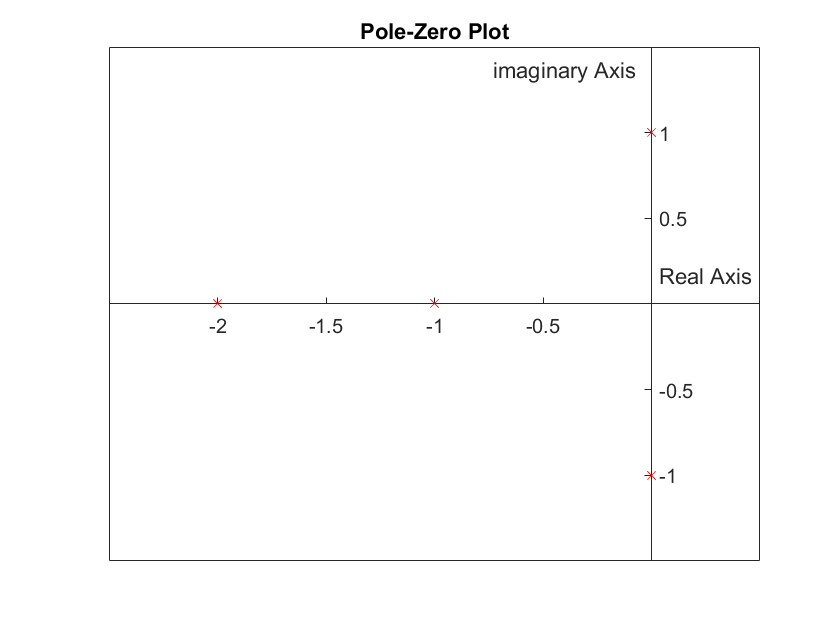

    plot(sysRoots,'X','Color','r');
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    xlabel("Real Axis")
    ylabel("Imaginary Axis")
    title("Pole-Zero Plot")

# 5.5 Application of R-H Criterion

## 5.5.1 Finding Loop Gain K

% Taking coefficients vector and organizing the first two rows
syms K k
fprintf('Always Enter the Gain as "K" i.e. in UpperCase\n');

Always Enter the Gain as "K" i.e. in UpperCase


First_Row_RH_Table = input('Input vector of First Row of RH Table: \n i.e. [an an-2 an-4 ... ] = ');
Second_Row_RH_Table = input('\nInput vector of First Row of RH Table: \n i.e. [an-1 an-3 an-5 ... ] = ');
Row_RH_Table =length(First_Row_RH_Table)+length(Second_Row_RH_Table);% length(Coeff_CE_Vector);
Col_RH_Table = round(Row_RH_Table/2);
RH_Table=[First_Row_RH_Table;Second_Row_RH_Table];

%% Calculate Routh-Hurwitz table's rows

%  Set epss as a small value
epss = 0.01;

%  Calculate other elements of the table
for i = 3:Row_RH_Table
    
    %  special case 1: zero in the first column
    if (RH_Table(i-1,1) == 0) 
        %Not all elements are zero i.e special case 2
        if (RH_Table(i-1,:) ~= 0)
        RH_Table(i-1,1) = epss;    %Assign Small Value E
        end
    end
   
    %  special case 2: row of all zeros
    if RH_Table(i-1,:) == 0
        sc=2;   %Special Case 2
        order = (Row_RH_Table - (i-1-1));   % Find the order of n-2 row
        cnt1 = 0;
        cnt2 = 1;
        for j = 1:Col_RH_Table - 1
            %New data = Derivative of Auxillary Equation
            %Derivative of auxillary means its order multiply by its...   
            %coeffcient
            RH_Table(i-1,j) = (order - cnt1) * RH_Table(i-2,cnt2);
            cnt2 = cnt2 + 1;   % Selection of next column
            cnt1 = cnt1 + 2;   % Order Decreases by 2 when we move to next column
        end
    end
    
    for j = 1:Col_RH_Table - 1
        %  first element of upper row
        firstElemUpperRow = RH_Table(i-1,1);
        
        %  compute each element of the table
        RH_Table(i,j) = ((RH_Table(i-1,1) * RH_Table(i-2,j+1)) - ....
            (RH_Table(i-2,1) * RH_Table(i-1,j+1))) / firstElemUpperRow;
    end
end
%   Print calculated data on screen
fprintf('\n Routh-Hurwitz Table:\n')


 Routh-Hurwitz Table:


RH_Table

$$RH\_Table = \left(\begin{array}{cc} \frac{1}{10} & 1\\ \frac{13}{20} & K\\ 1-\frac{2\,K}{13} & 0\\ K & 0 \end{array}\right)$$

% Solving for K
fprintf('The Value of Gain for stable system is\n');

The Value of Gain for stable system is


for i=3:Row_RH_Table
[~,~,condition]=solve(RH_Table(i,1)>0,K,'ReturnConditions',true);
display(condition);
end

$$condition = x<\frac{13}{2}$$

$$condition = 0<x$$

## 5.5.2 Finding Critical Gain

%Solving for Kcritical
for i=3:Row_RH_Table-1
Kcri=solve(RH_Table(i,1)==0,K);
display(Kcri);
end

$$Kcri = \frac{13}{2}$$

## 5.5.3 Finding Auxillary Equation and Frequency of Oscillation

% Finding Frequency of Oscillation
a=Kcri;
RH_Table=subs(RH_Table,K,a);    %Substituting the parameters

syms s w
for i = 3:Row_RH_Table
     %  special case 2: row of all zeros
    if RH_Table(i-1,:) == 0
        sc=2;   %Special Case 2
        order = (Row_RH_Table - (i-1-1));   % Find the order of n-2 row
        cnt1 = 0;
        cnt2 = 1;
        Aeqn=0;
        for j = 1:Col_RH_Table
            %New data = Derivative of Auxillary Equation
            %Derivative of auxillary means its order multiply by its...   
            %coeffcient
            Aeqn = Aeqn+s^(order - cnt1) * RH_Table(i-2,cnt2);
            cnt2 = cnt2 + 1;   % Selection of next column
            cnt1 = cnt1 + 2;   % Order Decreases by 2 when we move to next column
        end
        break;
    end
end
fprintf('Auxillary Equation is \n');

Auxillary Equation is 


display(Aeqn);

$$Aeqn = \frac{13\,s^{2}}{20}+\frac{13}{2}$$

% TO FIND Oscilaating Frequency
Aeqnw=subs(Aeqn,s,1j*w);
w_ans=solve(Aeqnw==0,w);
fprintf('\nFrequency of Oscillation is %f rad/sec\n',w_ans);


Frequency of Oscillation is 3.162278 

Frequency of Oscillation is -3.162278 


## 5.5.2 Relative Stability

clear ; close all; clc


% Taking coefficients vector and organizing the first two rows
Coeff_CE_Vector = input('input vector of your system coefficients: \n i.e. [an an-1 an-2 ... a0] = ');
sigma=input('\nEnter the shift factor to LH-side i.e. value of sigma\n');
Row_RH_Table = length(Coeff_CE_Vector);
order=Row_RH_Table;
%Defining the CE in Polynomial form
syms s z
CE=0;
for i=1:Row_RH_Table
CE=CE+Coeff_CE_Vector(i)*s^(order-i);
end

%Shifting the jw plane by sigma
CE=subs(CE,s,z-sigma);

%Finding the coefficient of the eqn
c = coeffs(CE);
Coeff_CE_Vector = fliplr(c);
fprintf('Coefficient of Shifted Characteristics Equation');

Coefficient of Shifted Characteristics Equation

display(Coeff_CE_Vector);

$$Coeff\_CE\_Vector = \left(\begin{array}{cccc} 1 & \frac{19}{2} & \frac{427}{25} & -\frac{451}{250} \end{array}\right)$$

%Coeff_CE_Vector = equationsToMatrix(CE,z);

%Rest is Same as of R-H Criterion
Col_RH_Table = round(Row_RH_Table/2);
%  Initialize Routh-Hurwitz table with empty zero array
RH_Table = zeros(Row_RH_Table,Col_RH_Table);

%  Compute first row of the table
RH_Table(1,:) = Coeff_CE_Vector(1,1:2:Row_RH_Table);

%  Check if length of coefficients vector is even or odd
if (rem(Row_RH_Table,2) ~= 0)
    % if odd, second row of table will be
    RH_Table(2,1:Col_RH_Table - 1) = Coeff_CE_Vector(1,2:2:Row_RH_Table);
else
    % if even, second row of table will be
    RH_Table(2,:) = Coeff_CE_Vector(1,2:2:Row_RH_Table);
end

%% Calculate Routh-Hurwitz table's rows

%  Set epss as a small value
epss = 0.01;

%  Calculate other elements of the table
for i = 3:Row_RH_Table
    
    %  special case 1: zero in the first column
    if (RH_Table(i-1,1) == 0) 
        %Not all elements are zero i.e special case 2
        if (RH_Table(i-1,:) ~= 0)
        RH_Table(i-1,1) = epss;    %Assign Small Value E
        end
    end
   
    %  special case 2: row of all zeros
    if RH_Table(i-1,:) == 0
        sc=2;   %Special Case 2
        order = (Row_RH_Table - (i-1-1));   % Find the order of n-2 row
        cnt1 = 0;
        cnt2 = 1;
        for j = 1:Col_RH_Table - 1
            %New data = Derivative of Auxillary Equation
            %Derivative of auxillary means its order multiply by its...   
            %coeffcient
            RH_Table(i-1,j) = (order - cnt1) * RH_Table(i-2,cnt2);
            cnt2 = cnt2 + 1;   % Selection of next column
            cnt1 = cnt1 + 2;   % Order Decreases by 2 when we move to next column
        end
    end
    
    for j = 1:Col_RH_Table - 1
        %  first element of upper row
        firstElemUpperRow = RH_Table(i-1,1);
        
        %  compute each element of the table
        RH_Table(i,j) = ((RH_Table(i-1,1) * RH_Table(i-2,j+1)) - ....
            (RH_Table(i-2,1) * RH_Table(i-1,j+1))) / firstElemUpperRow;
    end
    
    
    
end
%   Print calculated data on screen
fprintf('\n Routh-Hurwitz Table:\n')


 Routh-Hurwitz Table:


RH_Table

RH_Table =     1.0000   17.0800
    9.5000   -1.8040
   17.2699         0
   -1.8040         0



%%  Compute number of right hand side poles(unstable poles)
%   Initialize unstable poles with zero
unstablePoles = 0;

%   Check change in signs
for i = 1:Row_RH_Table - 1      %For comparing like Sorting Array
    if sign(RH_Table(i,1)) * sign(RH_Table(i+1,1)) == -1
        unstablePoles = unstablePoles + 1;
    end
end

%   Print the stability result on screen
if unstablePoles ~= 0
    fprintf('~~~~~> it is an unstable system! <~~~~~\n')
elseif sc==2  
    sysRoots = roots(Coeff_CE_Vector);
    % Repetitive roots on Imaginary Axis
    for i=1:Row_RH_Table-1    % One less roots than RH table Size
        for j=i+1:Row_RH_Table-1-1
    if(imag(sysRoots(i))==sysRoots(j))
         fprintf('~~~~~> it is an unstable system Due to Repetitive Roots on jw Axis! <~~~~~\n')
    end
        end
    end
    fprintf('~~~~~> it is a marginally stable system! <~~~~~\n')
else
    fprintf('~~~~~> it is a stable system! <~~~~~\n')
end

~~~~~> it is an unstable system! <~~~~~



fprintf('\n Number of right hand side poles =%2.0f\n',unstablePoles)  


 Number of right hand side poles = 1


# References

- Mathworks.inc

- Nise, Norman S. "Control system engineering, John Wiley & Sons." *Inc, New York*(2011).

- [https://ctms.engin.umich.edu/CTMS/index.php?aux=Home](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home)

- Bakshi, Uday A., and Varsha U. Bakshi. *Control system engineering*. Technical Publications, 2020.